# Image Properties

In the main window available different filters and features, which can help during manual annotation of the image.

## Show image

Allows users to turn on/off the image. If image is turned off, the black space will be shown.

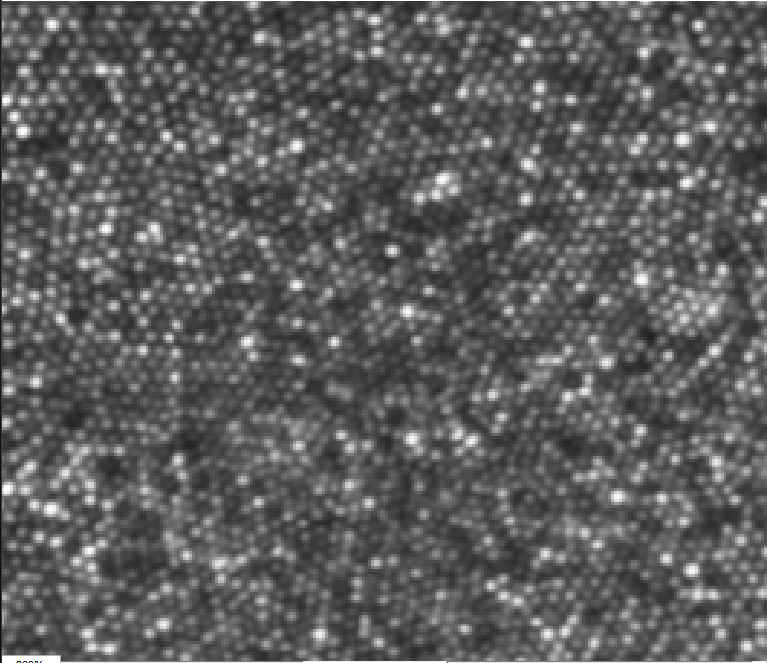

## Laplacian of Gaussian filter

Applies to image Laplacian of Gaussian filter with size = 5 and standard deviation = 0.35. Uses MATLAB inbuild function.

filter = fspecial('log', 5, 0.35);
image = imfilter(image, filter);

## 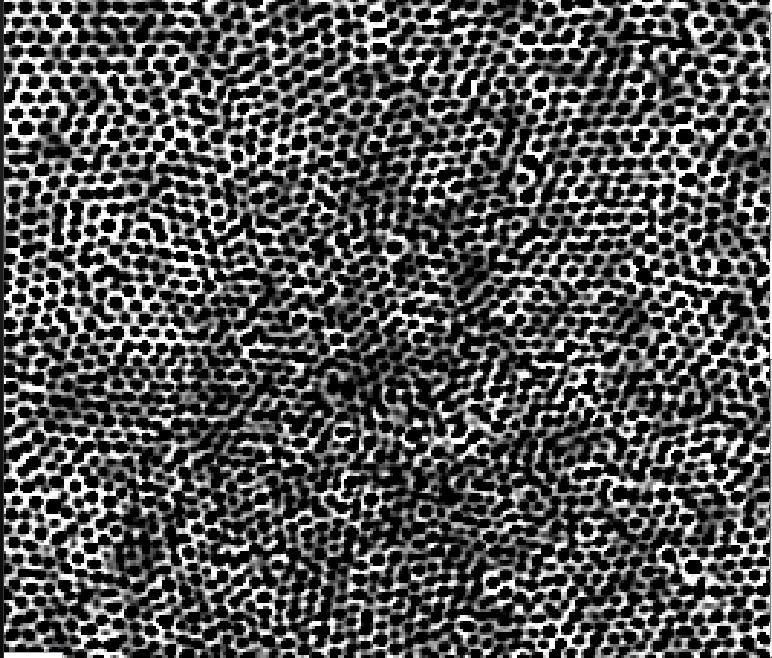

## Log filter

Applies to image Logarithmic filter. This filter scales brightness with formula:

$\textrm{newImage}=\frac{255}{\log \left(1+\max \left(\textrm{image}\right)\right)}*\log \left(\textrm{image}+1\right)$,

where **image** is each pixel of our image

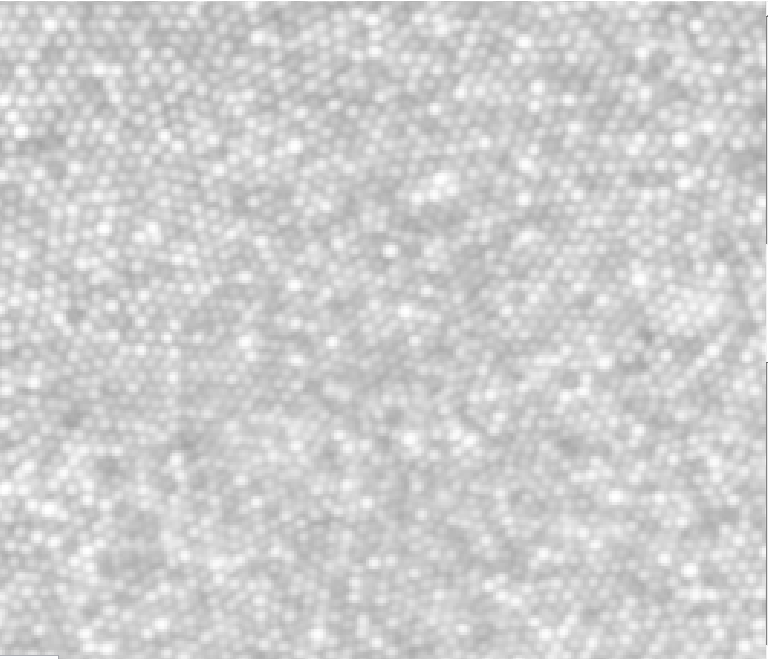

## Brightness

Slider from 0 to 2, which changes the brightness. Default value is 1.

Brightness adjustment happens by "imadjust" function.

newImage = imadjust(image, [], [], brightnessCoef)

## Show grid

Shows the grid over the image. Rough size of one square 135-150 pixels

## Show grid numbers

Shows number for each grid square. Works only if the Show grid option is on.